## Instructions: 

- If you haven't already done so, please go throught he live script "understanding_frequency_resonse.mlx" first before attempting this exercise. 

- Complete all the coding exercises. Specific instructions are provided for what is expected within the code snippets and the contextual text. 

- This assignment is intended as complementary material to lectures. Please take the time to read and understand all the material. 

## Interpreting Bode plots

Bode plots help us figure out the scaling factor and phase shift the system induces on a sinusoidal signal. We also saw that the scaling factor and the phase shift can be computed by substiting $s=j\omega$ in the transfer function, where $\omega$ is the angular frequency of he sinusoid. In this exercise, we ill verify this using some numerical computations. 

Consider the following system: 

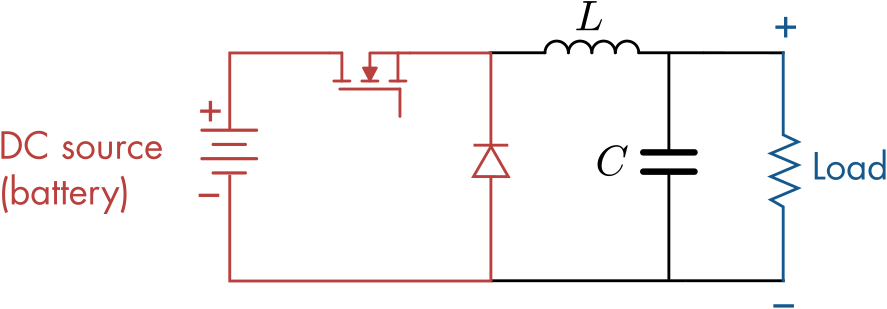

If we view the input $u(t)$ to the system as the voltage appearing across the diode, and the voltage $v(t)$ as the voltage accross the resistive load as the output, the transfer function is given as 


$$\frac{V}{U} = \frac{R}{LCRs^2 + Ls + R$$


### Transfer function 

 Express the transfer function as a symbolic function and store in $H(s)$ in the code below. 

%write your code here 
syms R L C postive 
syms s H(s) 

H(s) = R/(L*C*R*s^2 + L*s + R)

$$H(s) = \frac{R}{C\,L\,R\,s^{2}+L\,s+R}$$

### Response to a sinusoidal signal

Let us consider the case when $u(t)$ is a sinusoidal signal. For a sinusoidal input with angular frequency $\omega$, the scaling factor is given by $|H(j\omega)|$ and the phase shift is given by $\angle{H(j\omega)}$. Compute these two quantities for $\omega = 2\pi 500\times 10^3$rad/s below with values $L = 1$$\mu$H, $C = 5$$\mu$F, and $R = 5 \Omega$. Store the results as numbers (not symbolic expressions). Note: you can convert symbolic numbers into numeric values by using the `double()` function.  

%write your code here 
omega = 2*pi*500e3

omega = 3.1416e+06

response = subs(H(s),[s,L,C,R],[1j*omega,1e-6,5e-6,5]);
response = double(response)

response = -0.0207 - 0.0003i

%compute the scale in dB
scalew1 = 20*log10(abs(response))

scalew1 = -33.6883

%compute the phase value in degrees
phase1 = angle(response) *(180/pi)   

phase1 = -179.2554

### Bode plot

We will now ensure that the Bode plot is also providing the same information. 

clear L C R 
L = 1e-6; C=5e-6; R=5; 
Hn = tf(R, [L*C*R, L, R])

Hn =
 
              5
  -------------------------
  2.5e-11 s^2 + 1e-06 s + 5
 
Continuous-time transfer function.
Model Properties


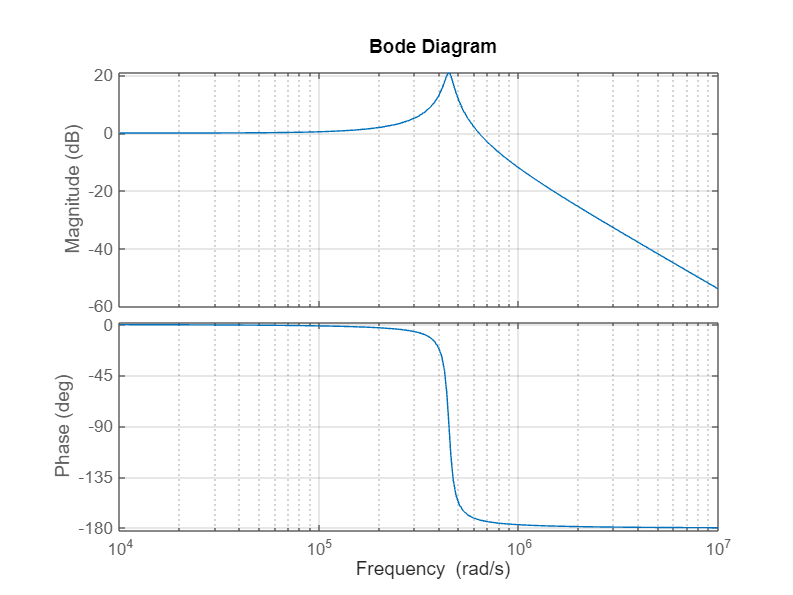

bode(Hn)
grid on

Verify the scaling factor and the phase shift you computed in the previous section match with what is shown in the Bode plot. 

Tip: When you click on the generated figure, you will see an arrow on the top right. That will open the figure in a new figure window where you will have more interactive options. Go to Tools->Data Tips to inspect individual values in the plot. 

**Comparison**

- According to the Bode plot, the magnitude response at 500 kHz should be between -35 dB to -32 dB which matches with the numeric value of approx -33 dB. The Bode plot can be regenerated with higher resolution for a more accurate answer. 

- The phase response at 500 kHz is approximately -179.2 degrees, again close to numerically computed value. 

### Time domain simulation

So far, we have analyzed the system in the frequency domain. We will now verify the same behavior in the time domain. 

Simulate the system for $20 ms$.

T = 100*(2*pi/omega)

T = 2.0000e-04

t = linspace(0,T,5000); 
u = sin(omega*t)

u =          0    0.1254    0.2487    0.3682    0.4818    0.5879    0.6847    0.7706    0.8444    0.9049    0.9511    0.9823    0.9980    0.9980    0.9822    0.9509    0.9047    0.8441    0.7702    0.6842    0.5874    0.4813    0.3676    0.2481    0.1247   -0.0006   -0.1260   -0.2493   -0.3688   -0.4824   -0.5884   -0.6851   -0.7710   -0.8448   -0.9052   -0.9513   -0.9825   -0.9981   -0.9980   -0.9821   -0.9507   -0.9044   -0.8438   -0.7698   -0.6837   -0.5869   -0.4807   -0.3670   -0.2475   -0.1241


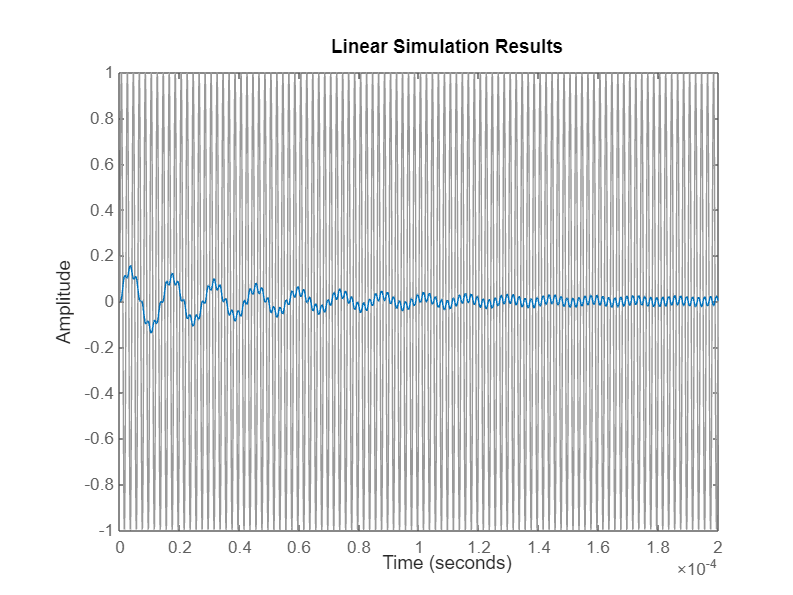

lsim(Hn,u,t)

Do you see the transient and the steady state part of the output? Compute the ripple (peak to peak) value of the signal during the steady state

%write your code here 
[y,tout] = lsim(Hn,u,t);
ripple = max(y(4000:end)) - min(y(4000:end))

ripple = 0.0508

Compute the scaling factor

scalew1TimeDomain = ripple/2 %2V is the peak to peak for input

scalew1TimeDomain = 0.0254

Scaling factor computed using transfer function

10^(scalew1/20)

ans = 0.0207

Are the scaling factors computing using time domain and transfer function close? 

## Application in filtering

We will now shift our attention to the practical context of filtering. The MOSFET shown in the circuit above is usually switched using PWM signals which are rectangular signals. We will use the Bode plot of the system to interpret the filtering action of the circuit.

From the Bode plot, we can see that the scaling factor for sinusoidal signals starts decreasing rapidly after about $500 \times 10^{3}$rad/s. Let us look at the response to the system for PWMs of two frequencies, one in the "pass band" of the filter and another in the "cut off" band of the filter in the code snippets below

%write your code here to simulate the system in time domain for a sinusoid
%in the "pass band" 

omegaPB = 3e5; 
T = 25*(2*pi/omegaPB)

T = 5.2360e-04

t = linspace(0,T,5000); 
u = sin(omegaPB*t)

u =          0    0.0314    0.0628    0.0941    0.1254    0.1565    0.1874    0.2182    0.2487    0.2790    0.3091    0.3388    0.3682    0.3972    0.4259    0.4541    0.4818    0.5091    0.5359    0.5622    0.5879    0.6130    0.6375    0.6614    0.6847    0.7072    0.7291    0.7502    0.7706    0.7903    0.8091    0.8272    0.8444    0.8608    0.8764    0.8911    0.9049    0.9178    0.9299    0.9410    0.9511    0.9604    0.9686    0.9760    0.9823    0.9877    0.9922    0.9956    0.9980    0.9995


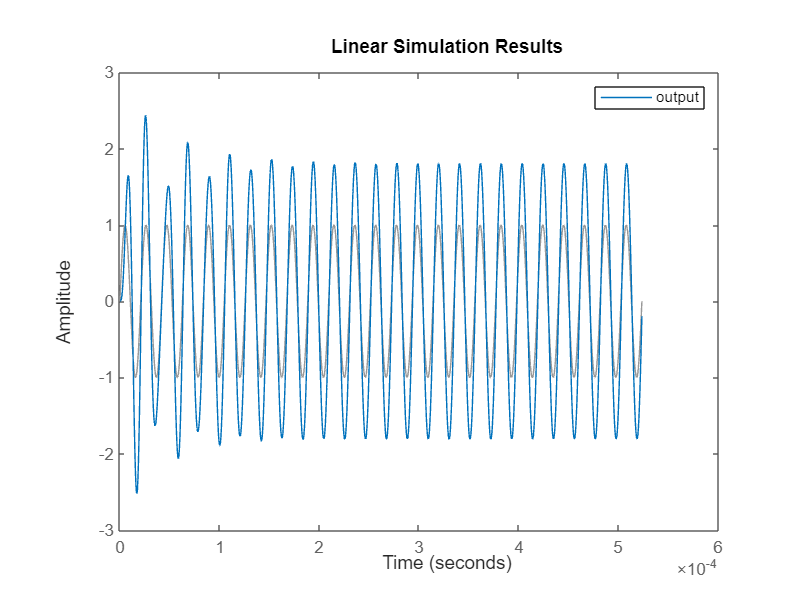

lsim(Hn,u,t)
legend('output')

Do you see the input frequency getting attenuated in the steady state? Now, let us do the same for another frequency in the cut-off region

%write your code here to simulate the system in time domain for a sinusoid
%in the "cutt-off region"

omegaPB = 3e6; 
T = 50*(2*pi/omegaPB)

T = 1.0472e-04

t = linspace(0,T,5000); 
u = sin(omegaPB*t)

u =          0    0.0628    0.1254    0.1874    0.2487    0.3091    0.3682    0.4259    0.4818    0.5359    0.5879    0.6375    0.6847    0.7291    0.7706    0.8091    0.8444    0.8764    0.9049    0.9299    0.9511    0.9686    0.9823    0.9922    0.9980    1.0000    0.9980    0.9921    0.9822    0.9685    0.9509    0.9296    0.9047    0.8761    0.8441    0.8088    0.7702    0.7287    0.6842    0.6370    0.5874    0.5354    0.4813    0.4253    0.3676    0.3085    0.2481    0.1868    0.1247    0.0622


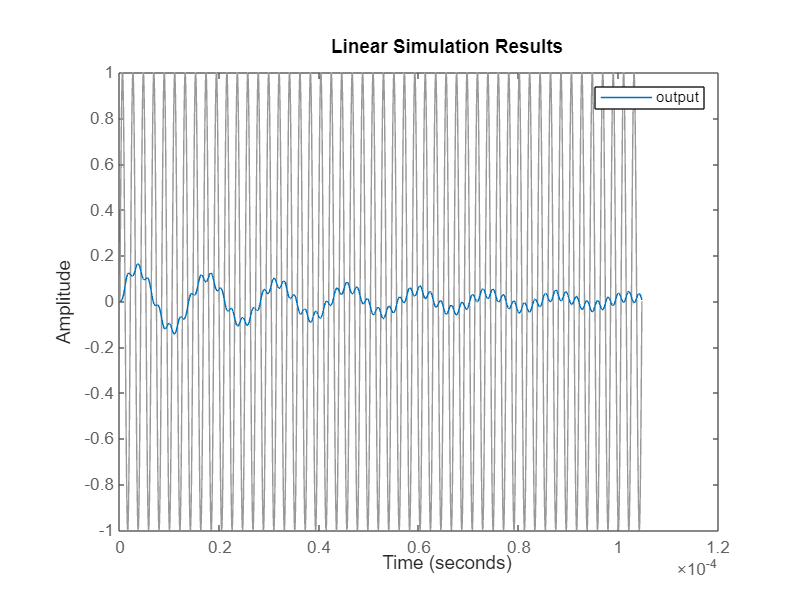

lsim(Hn,u,t)
legend('output')

Can you see the difference in the two cases? Now we will see how this applies to the filtering case. 

### Simulating the system with PWM inputs for different frequencies

The code below generates a PWM signal 

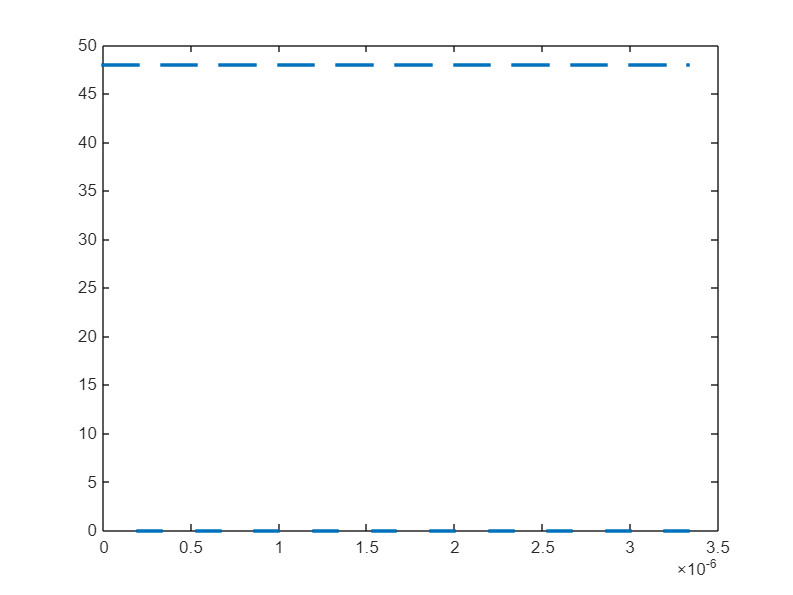

f =  3e6; % Set this                   % Switching frequency [Hz]
d = 0.6;                                % Duty cycle in [0,1]
cycles = 10;                           % Number of cycles to simulate
M = 48;                                 % Magnitude [V]
t = linspace(0,cycles/f,100*cycles);    % time variable array
u = switchedInput(t,f,d,M);             % The input function u(t)
plot(t,u,'.')

We will use the PWM signal as the input to our system and simulate it in time domain 

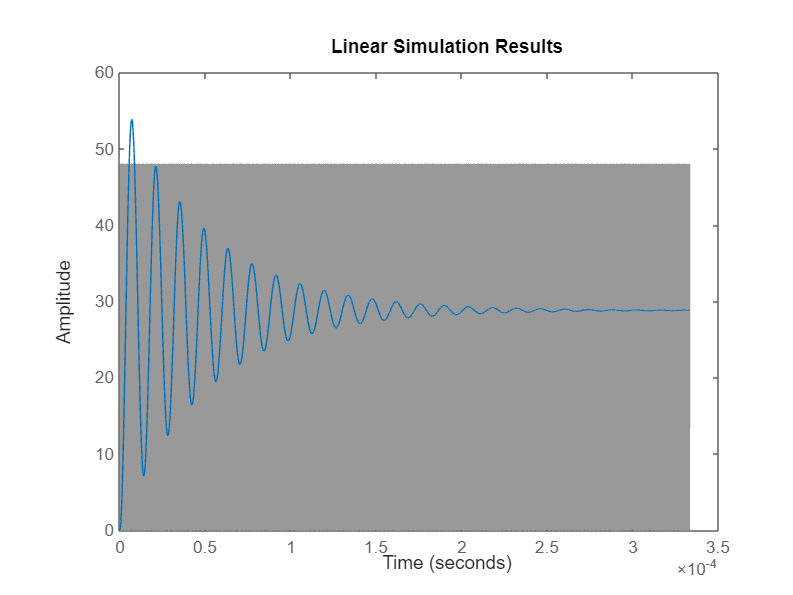

cycles = 1000;                           % Number of cycles to simulate
M = 48;                                 % Magnitude [V]
t = linspace(0,cycles/f,100*cycles);    % time variable array
u = switchedInput(t,f,d,M);  
lsim(Hn,u,t)

**Reflect**

- In which of the two cases above does the steady state output resemble a DC signal closely? 

- If you had to chose a PWM signal frequency for this DC to DC converter, which frequency would you chose? 

### Interpreting the response to the PWM signals using Bode plot

Let us inspect the frequency spectrum of the PWM signals we explored in the previous section. 

First, let us generate the PWM signals

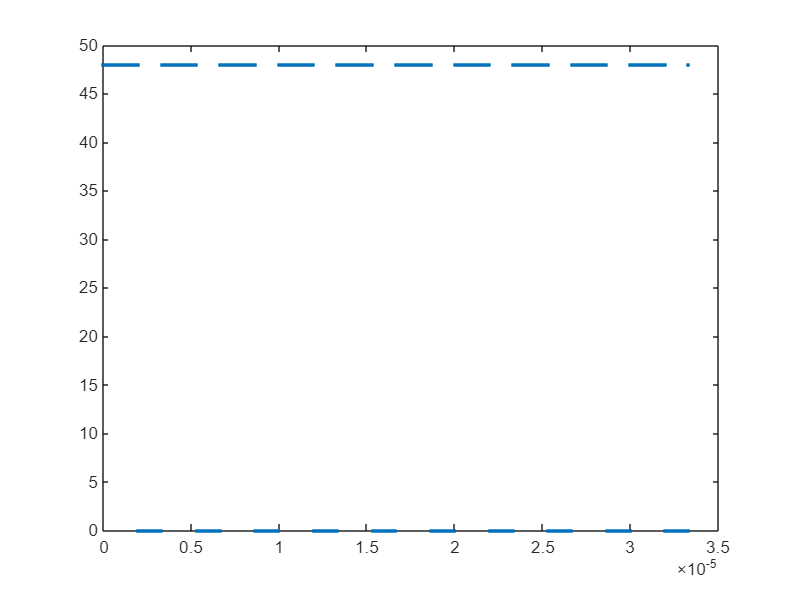

f =  3e5; % Set this                   % Switching frequency [Hz]
d = 0.6;                                % Duty cycle in [0,1]
cycles = 10;                           % Number of cycles to simulate
M = 48;                                 % Magnitude [V]
t = linspace(0,cycles/f,100*cycles);    % time variable array
u = switchedInput(t,f,d,M);             % The input function u(t)
plot(t,u,'.')

Look at its frequency spectrum 

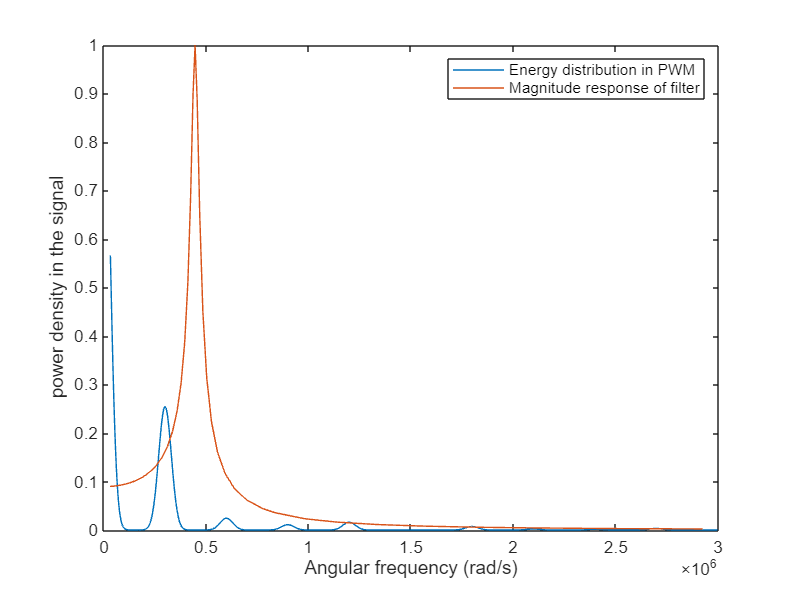

samplingRate = 1/(t(2)-t(1)); 
[p,frequencies] = pspectrum(u,samplingRate);
p = p./max(p); %normalizaing for better visualization


[mag,phase,wout] = bode(Hn);
mag = mag(:); 
mag = mag./max(mag); %normalizaing for better visualization


select = frequencies > 0.1*f & frequencies < 10*f; 
plot(frequencies(select),p(select))
xlabel('Angular frequency (rad/s)')
ylabel('power density in the signal')

hold on
select = wout > 0.1*f & wout < 10*f; 
plot(wout(select), mag(select))
hold off
legend('Energy distribution in PWM', 'Magnitude response of filter')

The plot shows how the energy (power) is distributed in various frequencies in the signal. The red vertical line shows the transition frequency between the pass-band and the cut-off band of the filter observed in the Bode plot 

**Reflect: **

- In which of the two cases does the the filter allow the first harmonic in the signal to pass? 

- Does it allow the DC part of the signal to pass in both cases? 

**Answers:**

-  The first harmnoic is in the pass pand when the PWM frequency is 3x10^5 rad/s.

-  In both cases, the DC part is in the pass band of the filter. 

function u = switchedInput(t,f,d,M)
    % Generates a shifted square wave with a magnitude specified by M, 
    % a duty cycle d, and frequency f
    u = M*(mod(t,1/f) < d/f);
end